%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



## set AutocorrelationFunction class parameters

start_point = 3748;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

%% generate AutocorrelationFunciton instance and confirm properties
autocorrelation_function = AutocorrelationFunction(audio_file_manipulator.signal(start_point : start_point + continue_point - 1));
autocorrelation_function.calculate_autocorrelation_with_fourier();
autocorrelation_function.display_properties();

--------------------------------------------
--------- Auto correlation function --------
signal size : (706, 1)
autocorrelation size : (706, 1)
power_spectrum size : (2048, 1)
fft_point : 2048 [point]
--------------------------------------------



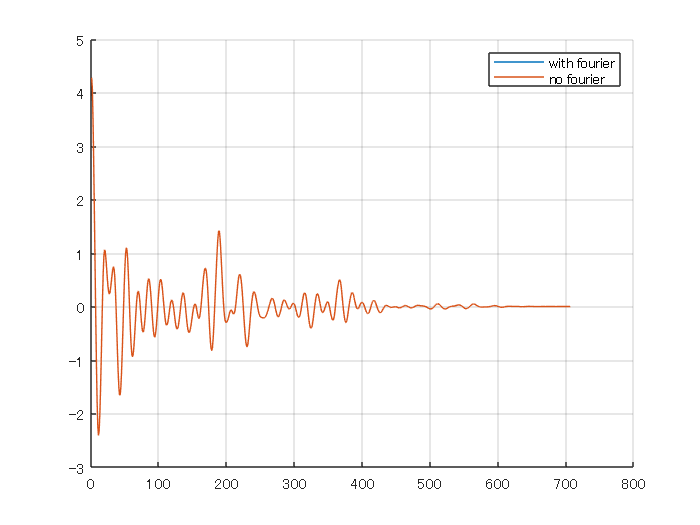

hold on;
grid on;
legend;
plot(autocorrelation_function.autocorrelation, "DisplayName", "with fourier");
autocorrelation_function.calculate_autocorrelation();
plot(autocorrelation_function.autocorrelation, "DisplayName", "no fourier");